# Common Params

% Parameters
ymax = 0.008;       % Max y-distance from origin
xmax = 0.002;       % Max x-distance from origin
dz = 0.0015;     % Deviation in height from start
z_init = 0.002;    % Starting z-value
tmax = 30;      % Assumed duration of path tracing

t = linspace(0, tmax, 1000);  % Time (in seconds)  
% ^ DEFINE: tmax (in seconds) is where measurement ENDS; helix dimensions
% are decided based on this!

## Helix (Tornado)

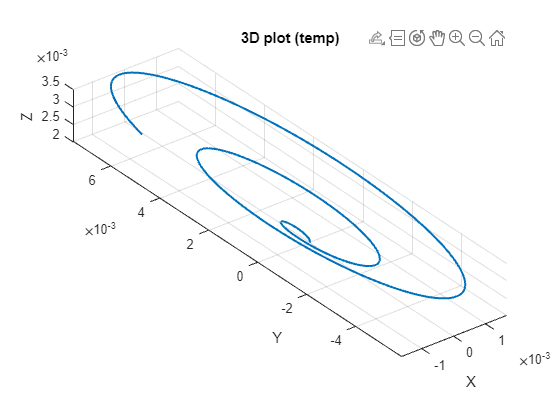

freq = 0.08;     % turns per second (helix only)

% Parametric equations
x = (xmax * t / tmax) .* cos(2*pi*freq * t);
y = (ymax * t / tmax) .* sin(2*pi*freq * t);
z = z_init + (dz) * t / tmax;

% Plotting
figure;
plot3(x, y, z, 'LineWidth', 1.5);
grid on;
xlabel('X');
ylabel('Y');
zlabel('Z');
title('3D plot (temp)');
axis equal;

# Helix (Drill)

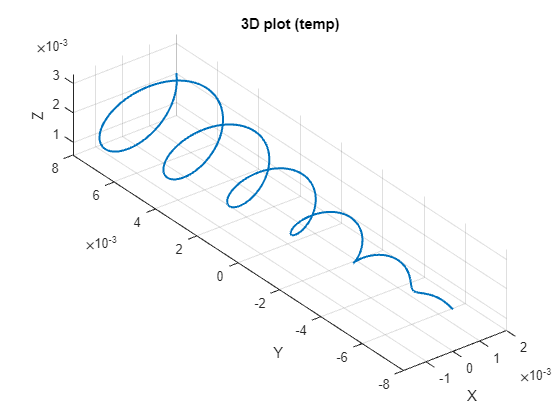

freq = 0.2;     % turns per second (helix only)

% Parametric equations
x = (xmax * t / tmax) .* cos(2*pi*freq * t);
y = -ymax + (2*ymax * t / tmax);
z = z_init + (dz) * t / tmax  .* sin(2*pi*freq * t);

% Plotting
figure;
plot3(x, y, z, 'LineWidth', 1.5);
grid on;
xlabel('X');
ylabel('Y');
zlabel('Z');
title('3D plot (temp)');
axis equal;

# Oval

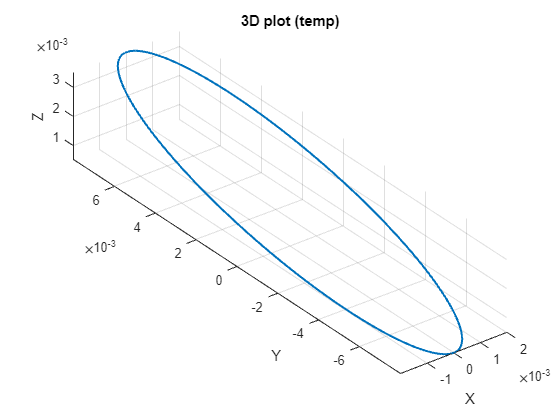

freq = 1/30;     % turns per second (helix only)

% Parametric equations
x = (xmax ) .* cos(2*pi*freq * t);
y = (ymax ) .* sin(2*pi*freq * t);
z = z_init + (dz) * sin(2*pi*freq * t);

% Plotting
figure;
plot3(x, y, z, 'LineWidth', 1.5);
grid on;
xlabel('X');
ylabel('Y');
zlabel('Z');
title('3D plot (temp)');
axis equal;

# Figure 8

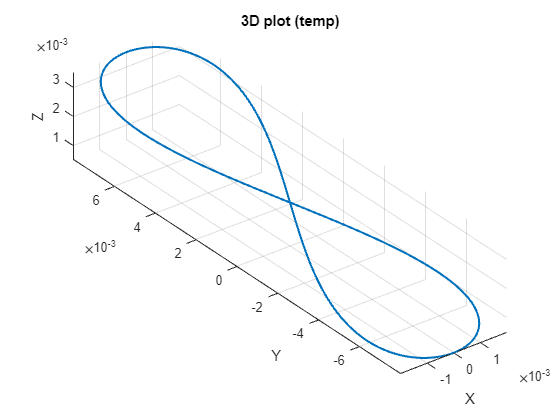

freq = 0.2;     % turns per second (helix only)

% Parametric equations
x = (xmax ) .* sin(2*pi*freq * 2*t);
y = (ymax ) .* sin(2*pi*freq * t);
z = z_init + (dz) * sin(2*pi*freq * t);

% Plotting
figure;
plot3(x, y, z, 'LineWidth', 1.5);
grid on;
xlabel('X');
ylabel('Y');
zlabel('Z');
title('3D plot (temp)');
axis equal;

# Rectangle

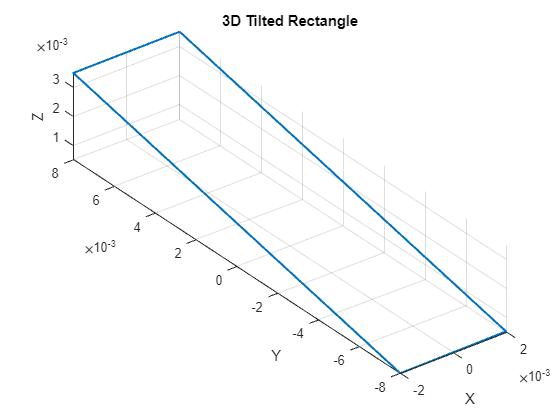

% Parameters
w = 2*xmax;    % Width of the rectangle
h = 2*ymax;    % Height of the rectangle
k = dz / ymax;    % Tilt factor for the z-direction (rise/run)

% Parametric equations
x = zeros(size(t));
y = zeros(size(t));
z = zeros(size(t));

% Define each segment of the rectangle based on the proportional value of t
segment = t / (tmax / 4);  % Scale t to 4 segments

% First edge (right vertical)
x(segment < 1) = w / 2;
y(segment < 1) = h / 2 - segment(segment < 1) * h;
z(segment < 1) = k * y(segment < 1) + z_init;

% Second edge (bottom horizontal)
x(segment >= 1 & segment < 2) = -w / 2;
y(segment >= 1 & segment < 2) = -h / 2;
z(segment >= 1 & segment < 2) = k * y(segment >= 1 & segment < 2)  + z_init;

% Third edge (left vertical)
x(segment >= 2 & segment < 3) = -w / 2;
y(segment >= 2 & segment < 3) = -h / 2 + (segment(segment >= 2 & segment < 3) - 2) * h;
z(segment >= 2 & segment < 3) = k * y(segment >= 2 & segment < 3) + z_init;

% Fourth edge (top horizontal)
x(segment >= 3 & segment <= 4) = w / 2;
y(segment >= 3 & segment <= 4) = h / 2;
z(segment >= 3 & segment <= 4) = k * y(segment >= 3 & segment <= 4) + z_init;

% Plotting
figure;
plot3(x, y, z, 'LineWidth', 1.5);
grid on;
xlabel('X');
ylabel('Y');
zlabel('Z');
title('3D Tilted Rectangle');
axis equal;